# **IO205 - Digital Output**

This example shows you how to use the IO205 to output digital signals and which settings you must first define.

The IO205 I/O module is a digital output module with Simulink® driver blocks. The 32 digital outputs are available as high-side switches with a 6 V to 48 V output range. All channels are galvanically isolated by optocouplers. All outputs are protected against short-circuit and thermal overload and can output up to 0.5 A per channel.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO205 I/O module installed

- Connector cable from the I/O module to the terminal board

- 50-pin terminal board with jumper wires

- External power supply (6 V to 48 V)

- Oscilloscope to measure the signals

### Pin Mapping/Connection Diagram/Test Setup

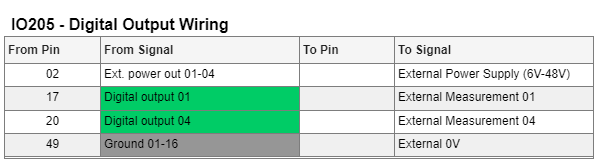

On the terminal board of the digital I/O module, connect pin 02 with the external power supply and pin 49 with the ground or 0 V of the power supply.

Connect pin 17 and pin 20 to the oscilloscope.

[IO205 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io205_pin_mapping)

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO205_DigitalOutput';
open_system(modelName);

### Model Description

The Simulink model features one [IO205 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io205_setup) block, one [IO205 Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io205_write) block and one [Pulse Generator](https://ch.mathworks.com/help/simulink/slref/pulsegenerator.html) block.

The [Pulse Generator](https://ch.mathworks.com/help/simulink/slref/pulsegenerator.html) block generates a square wave which then propagates to the [IO205 Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io205_write) block. Please note that the [Pulse Generator](https://ch.mathworks.com/help/simulink/slref/pulsegenerator.html) has two different phase shifts configured as a vector. This parameter allows better visualization of the two signals.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode
% set_param(modelName,'SimulationCommand','start')      % start real-time application through Simulink toolstrip

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;


### Check the Results

The blue signal is channel 1 and the red signal is channel 4 of the [IO205 Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io205_write) block.

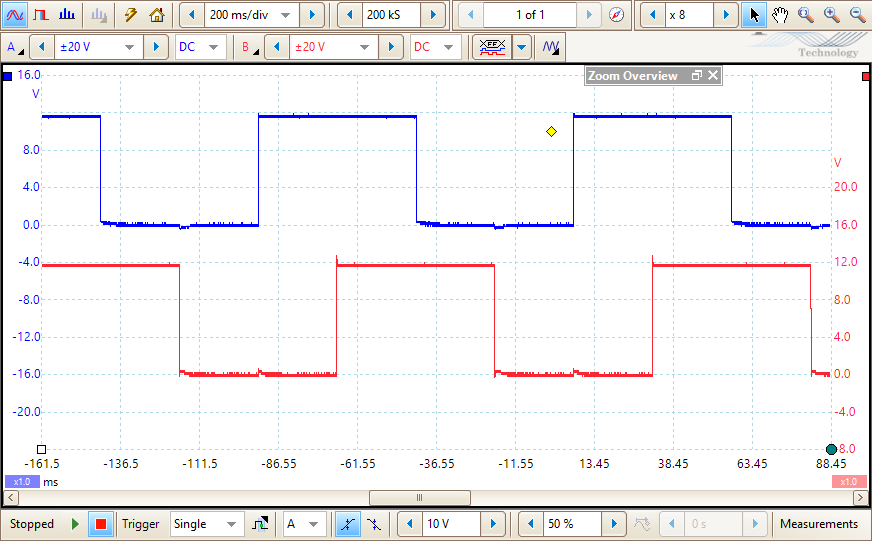

## Additional References

- [IO205 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io205)